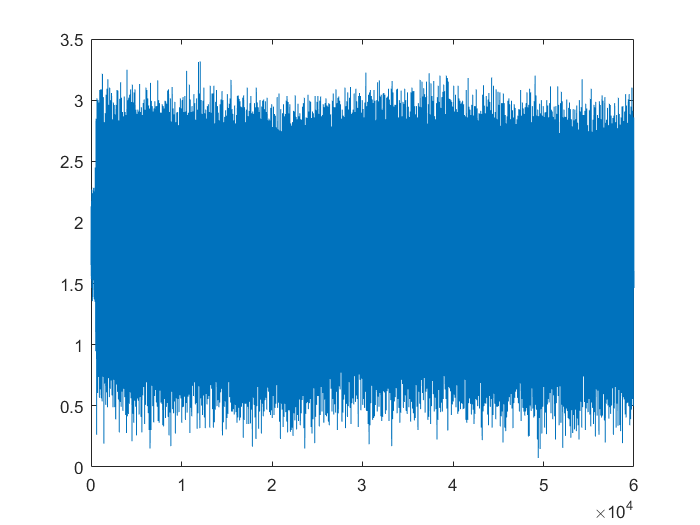

% clear
load("data/daq_sin.mat");
y = data.y(1:end);
plot(y)

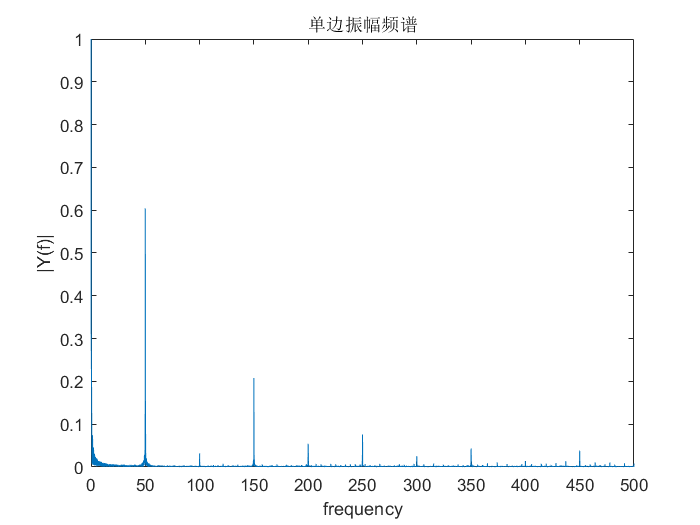


Fs = 5000;

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

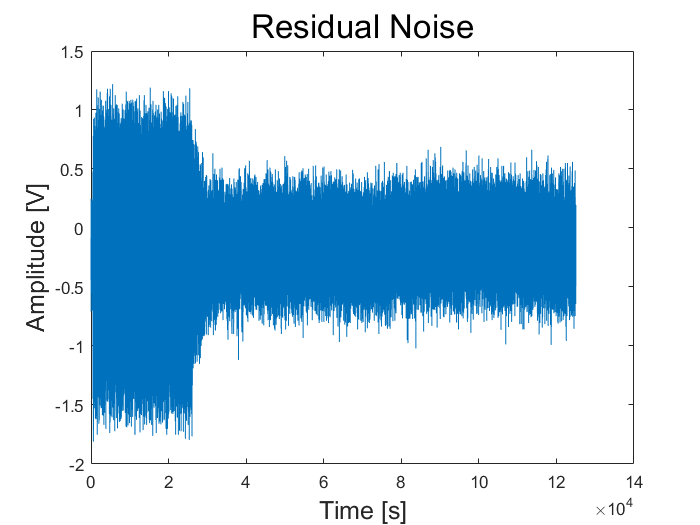

% clear
load("bandpass50.mat")
load("data/daq_wrapper.mat");
y = data.y(1:end);
plot(y)

title("Residual Noise", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);

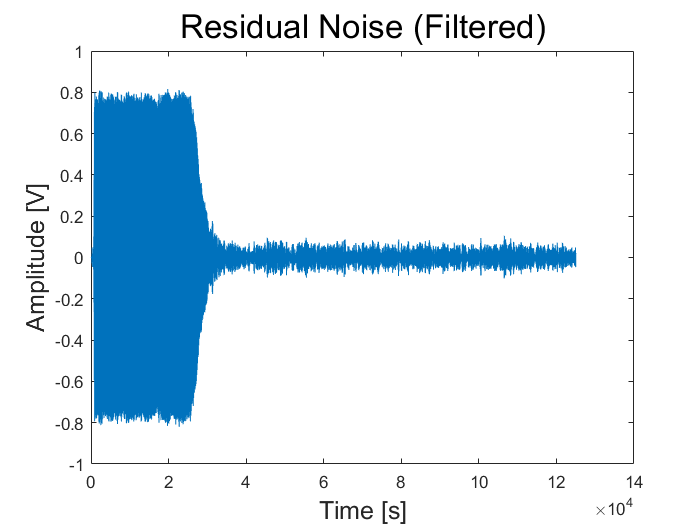


plot(filter(bandpass50,y))

title("Residual Noise (Filtered)", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);

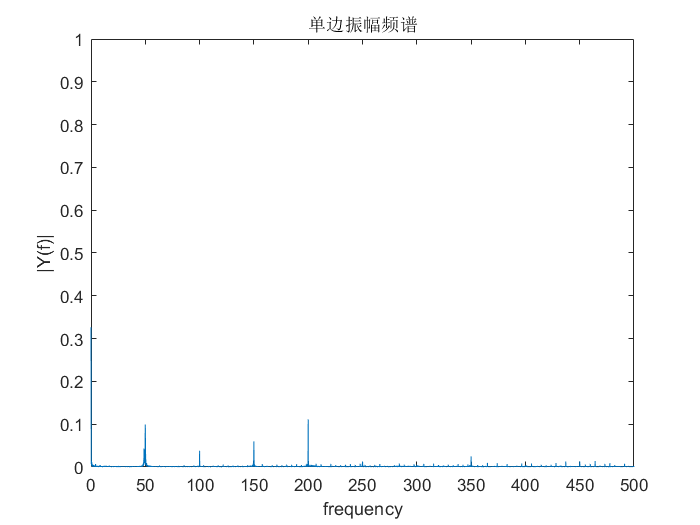


Fs = 5000;

y = data.y(10000:end);

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

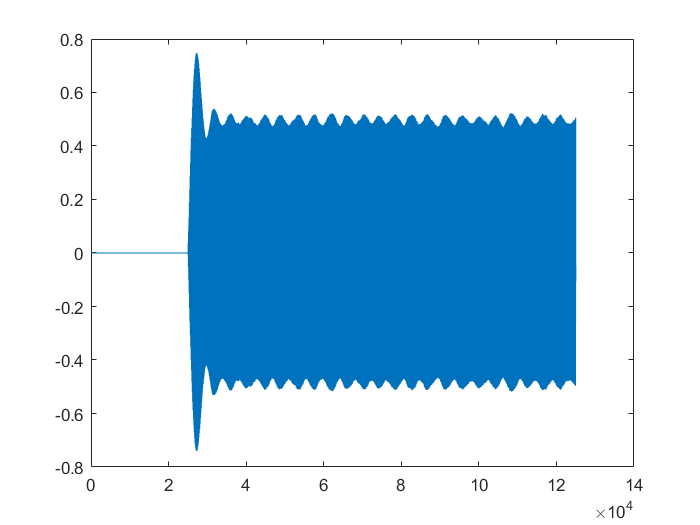




u = data.u(1:end);
plot(u)

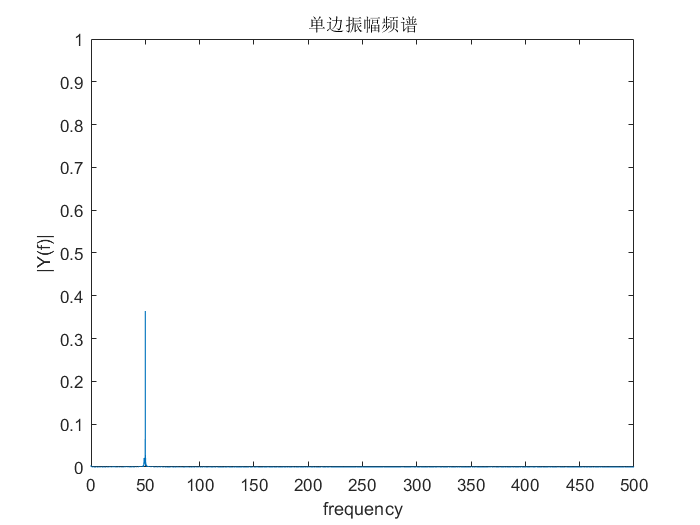

Fs = 5000;

[f, p] = fftFunc(Fs, length(u), u);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])


fig = figure;
N = Fs;
im = cell(1, 20);
x = (1:length(y))/Fs;

yf =     0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0007    0.0007    0.0007    0.0006    0.0006    0.0005    0.0004    0.0003    0.0002    0.0001   -0.0001   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0013   -0.0016   -0.0018


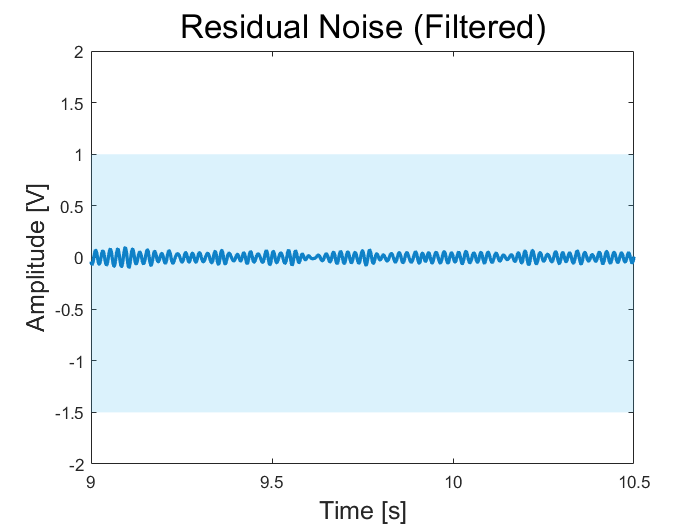

plot(x, y, 'LineWidth', 2);

p = patch('vertices', [0, -1.5; 0, 1.0; 20, 1.0; 20 -1.5], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
title("Residual Noise (Filtered)", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);
for i = 1:120
    ts = i*0.075;
    ylim([-2, 2])
    xlim([ts, ts+1.5]);
%     pause(0.075);
    % 注释下面两句话可以看到动态输出
        frame = getframe(fig);
        im{i} = frame2im(frame);
end

% % 下面是保存成 gif
filename = 'y_real.gif';
for idx = 1:120
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.075);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.075);
    end
end

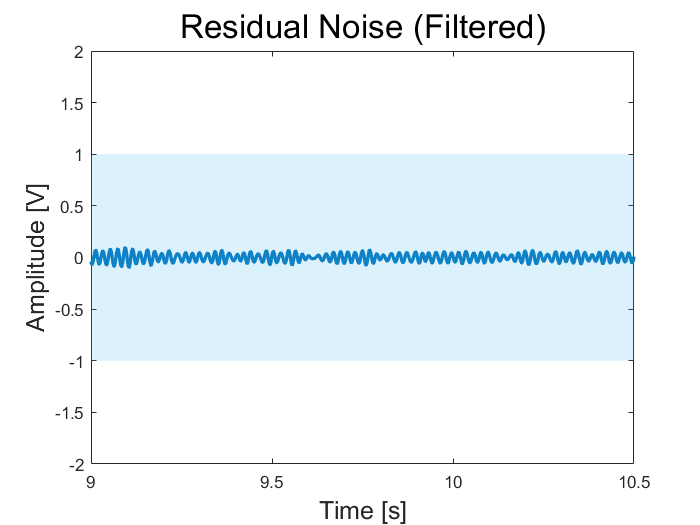


fig = figure;
N = Fs;
im = cell(1, 20);
x = (1:length(y))/Fs;
yf = filter(bandpass50,y);
plot(x, yf, 'LineWidth', 2);

p = patch('vertices', [0, -1.0; 0, 1.0; 20, 1.0; 20 -1.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
title("Residual Noise (Filtered)", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);

for i = 1:120
    ts = i*0.075;
    ylim([-2, 2])
    xlim([ts, ts+1.5]);
%     pause(0.075);
    % 注释下面两句话可以看到动态输出
        frame = getframe(fig);
        im{i} = frame2im(frame);
end

% % 下面是保存成 gif
filename = 'y_filtered.gif';
for idx = 1:120
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.075);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.075);
    end
end

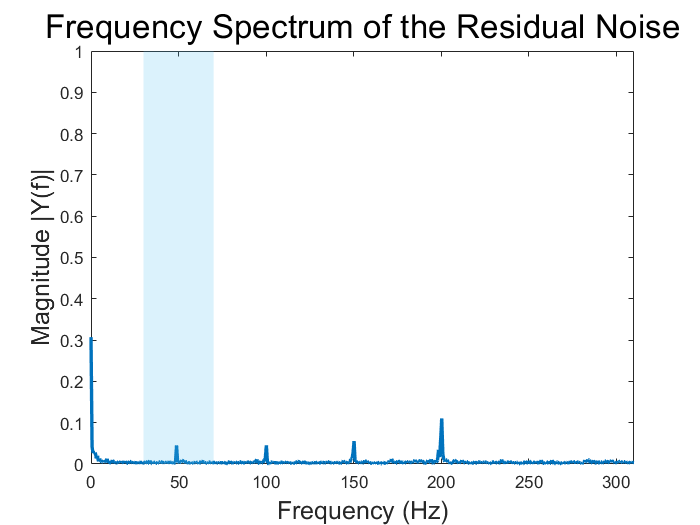


fig = figure;
N = Fs;
im = cell(1, 120);

for i = 1:120

yn = y((i*Fs*0.075):(i*Fs*0.075+1.5*Fs));
[f, p] = fftFunc(Fs, length(yn), yn);

plot(f, p, 'LineWidth', 2)
xlim([0, 310])
ylim([0, 1])
title("Frequency Spectrum of the Residual Noise", "FontSize", 20);
ylabel("Magnitude |Y(f)|","FontSize", 15);
xlabel("Frequency (Hz)","FontSize", 15);

p = patch('vertices', [30, 0.0; 30, 1.0; 70, 1.0; 70 0.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');

% pause(0.075);
%     % 注释下面两句话可以看到动态输出
        frame = getframe(fig);
        im{i} = frame2im(frame);
end

% 下面是保存成 gif
filename = 'y_fft.gif';
for idx = 1:120
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.075);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.075);
    end
end

function [f, p] = fftFunc(Fs, L, y)
T= 1/Fs; %采样时间
t = (0:L-1)*T; %时间向量
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end